%Para grabacion con matlab
%muestras/s - bit por muestra - canales - Dispositivo
recObj = audiorecorder(8000,16,1,-1)  %Objeto grabador de audio

recObj =   audiorecorder with properties:

       SampleRate: 8000
    BitsPerSample: 16
      NumChannels: 1
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 0
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audiorecorder'


recordblocking(recObj, 5);%Grabación
%play(recObj);%Reproduce sonido 
voz = getaudiodata(recObj)%Almacena datos grabados en un array double

voz =          0
         0
   -0.0000
         0
         0
         0
         0
   -0.0000
         0
         0


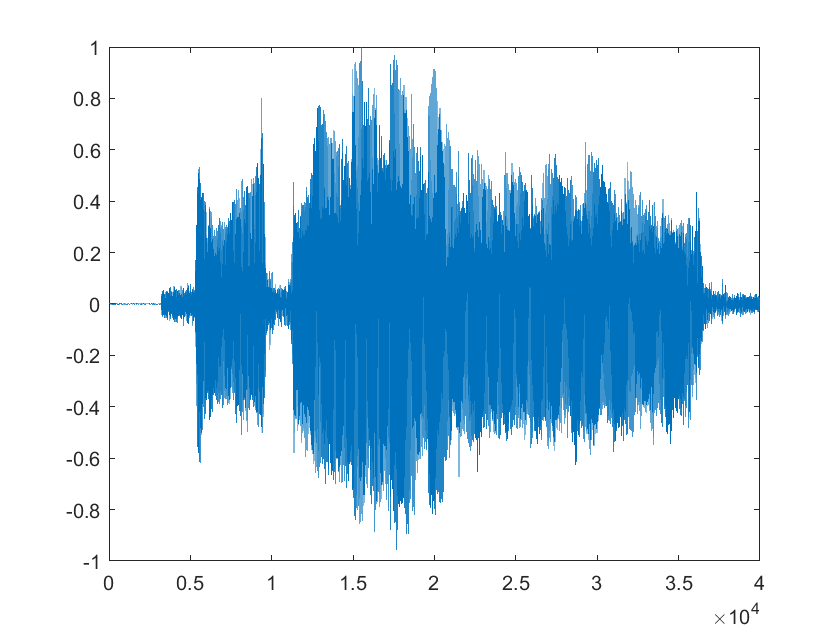

vn=voz/(max(voz)+0.0001);%se normaliza la voz al intervalo entre 0 y 1
plot(vn)

max(vn)

ans = 0.9991

%calculo de la amplitud segun la SNR
N=length(vn);
yrms=sqrt((1/N)*sum(vn.^2)) %valor rms de la señal

yrms = 0.2627

yrms=yrms(1,1)

yrms = 0.2627


$$\textrm{SNR}\left(\textrm{db}\right)=20\log \left(\frac{R_S }{R_n }\right)$$


%valor rms de Rla señal de ruido
rmsr=yrms/(10^(5/20))

rmsr = 0.1477

%valor pico de la señal de ruido
vpr=rmsr*sqrt(2)

vpr = 0.2089

%Calculo de la frecuencia del tono
ft=6*50

ft = 300

%Guarda los datos de voz
lee=fopen("voz.dat",'w+');
fprintf(lee,'%12f\n',vn);
fclose(lee);

%filtrado
del=2;
fc=300;
wc=2*[fc-del fc+del]/8000;
n=1;%IIR
[b,a]=butter(n,wc,'stop')

b =     0.9984   -1.9417    0.9984


a =     1.0000   -1.9417    0.9969


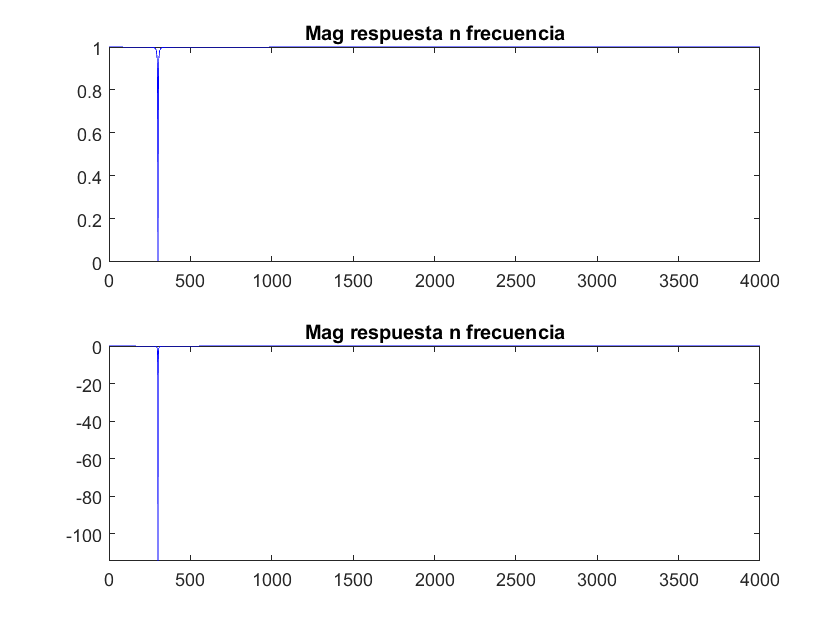

[H4,w]=freqz(b,a,4000);

figure(1)
subplot(211)
plot(abs(H4),'b')
title('Mag respuesta n frecuencia')
subplot(212)
plot(20*log(abs(H4)),'b')
title('Mag respuesta n frecuencia')

%play(recObj);%Reproduce sonido 

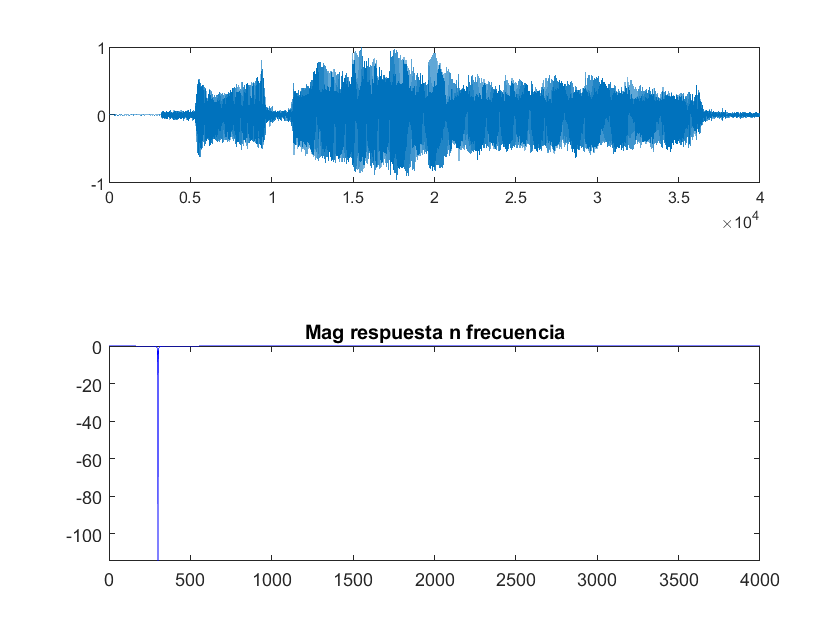

arc=importdata("salsfil.dat");
arc2=importdata("salfil.dat");
subplot(311)
plot(vn)

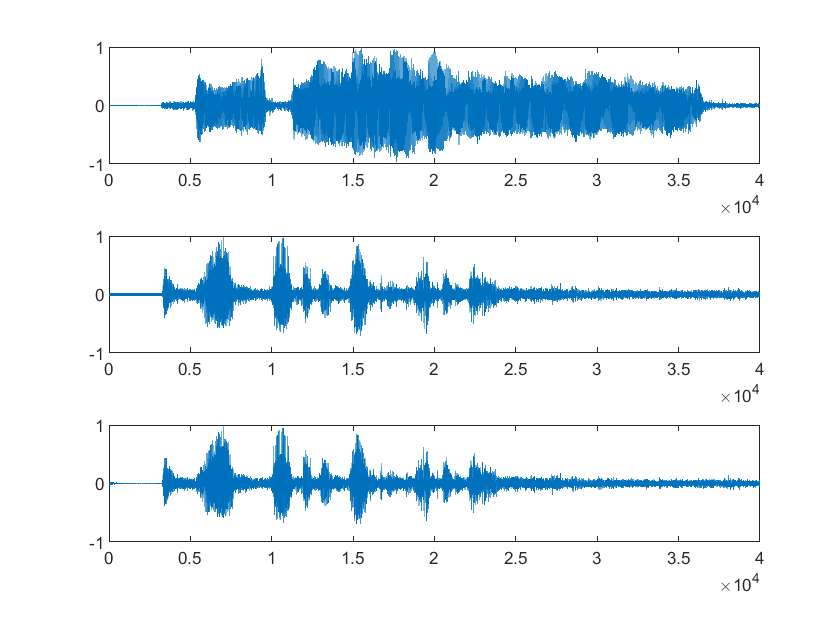

subplot(312)
plot(arc(:,2))
subplot(313)
plot(arc2(:,2))

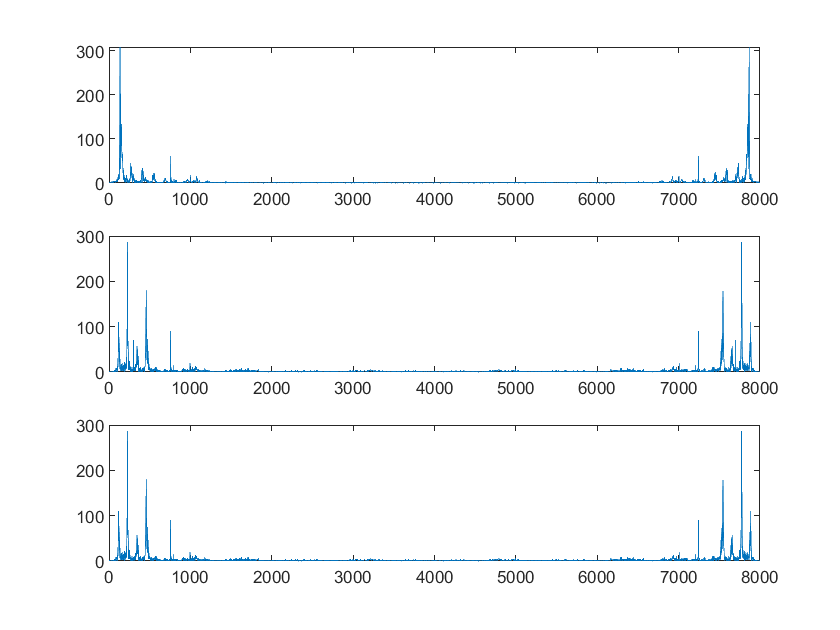


figure
s1=fft(vn,8000);
subplot(311)
plot(abs(s1))
subplot(312)
s2=fft(arc(:,2),8000);
plot(abs(s2))
subplot(313)
s3=fft(arc2(:,2),8000);
plot(abs(s3))

sound(vn,8000)

sound(arc,8000)

sound(arc2,8000)

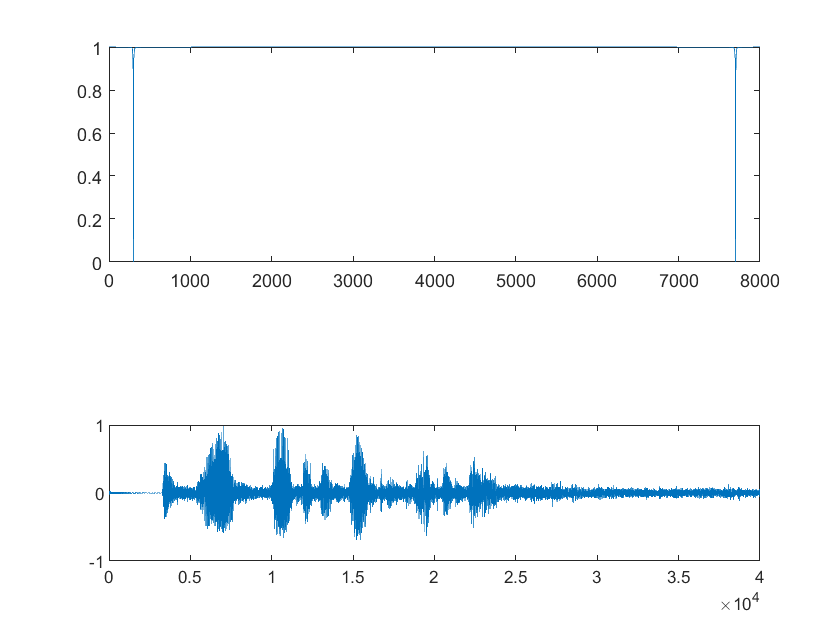

figure(1)
arc=importdata("espsis1.dat");
arc2=importdata("espsis2.dat");
subplot(211)
plot(arc(:,1)*8000/(2*pi()),arc(:,2))

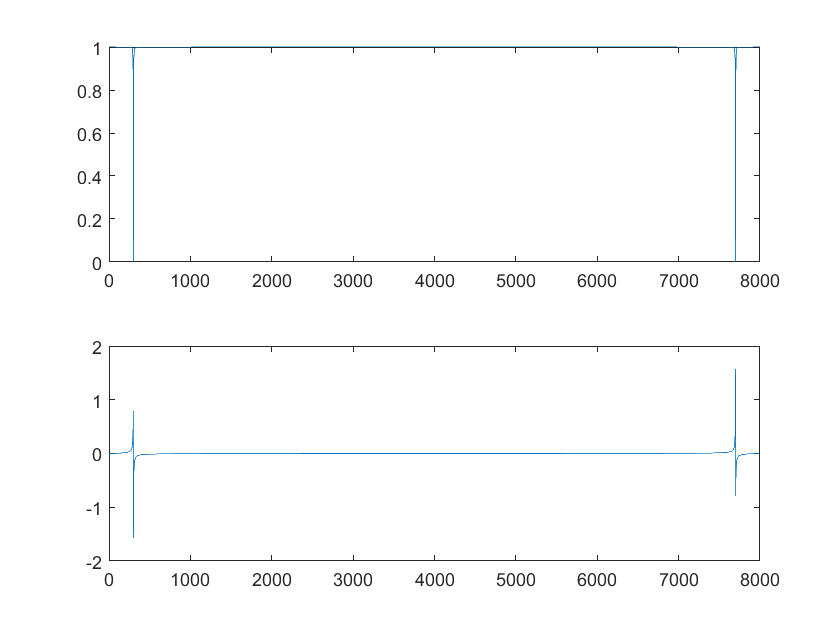

subplot(212)
plot(arc(:,1)*8000/(2*pi()),arc2(:,2))

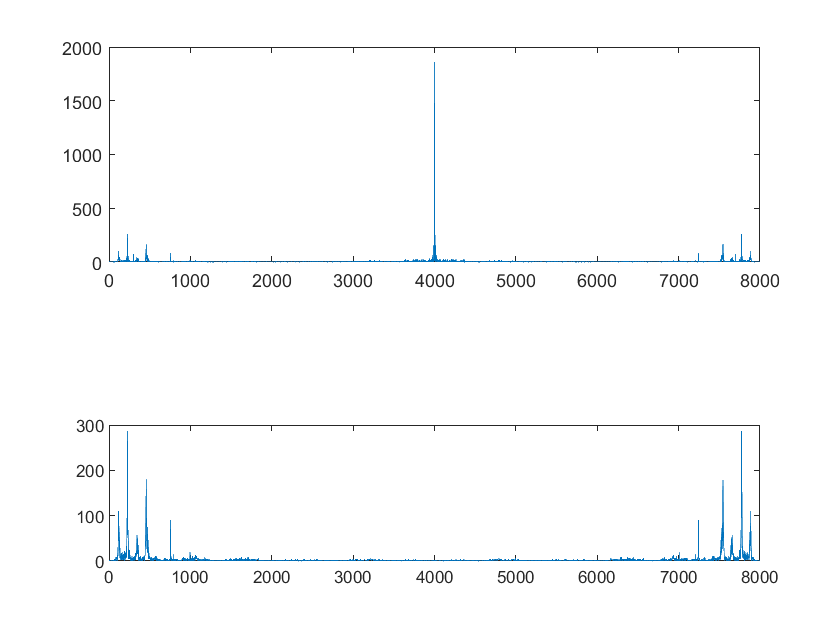


figure(2)
arc=importdata("espin.dat");
arc2=importdata("espout.dat");
subplot(211)
plot(arc)

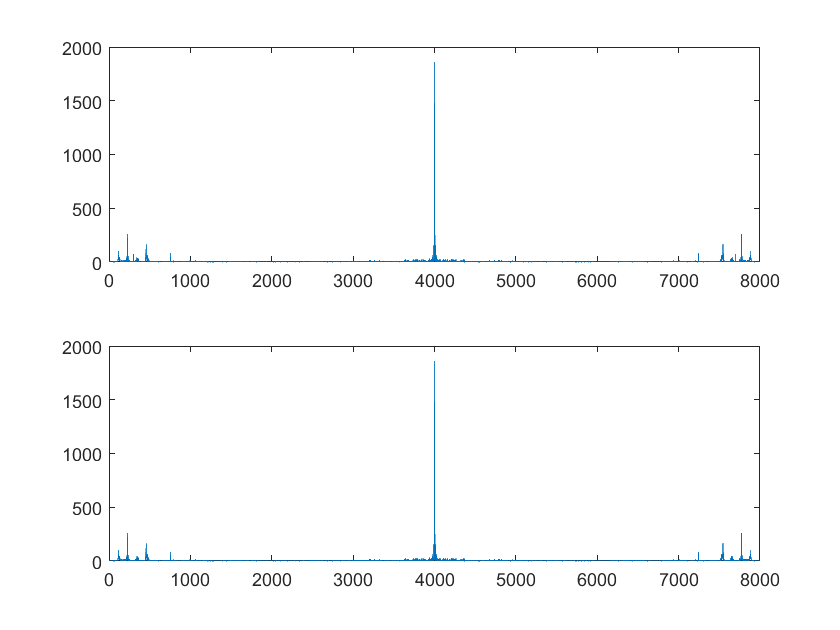

subplot(212)
plot(arc2)